# Bayesian parameter inference

In this tutorial we will learn how to perform a simple Bayesian analysis. By now you and your TA must have discussed the different interpretations of probability between the two classic schools of thought Bayesians and frequentists. In a debate that spans over centuries there is a lot of literature about these differences and how it influences the way we interpret our data and how we do science in general.

Here we won't focus on this discussion, but we will approach the subject from a pragmatic point of view. For our example we will be using data from a recent publication from the Phillips group.... (to be continued)

# Exploratory Data analysis.

The first step on every analysis should always be an exploration of the data. What this means is that we have to get a sense of not only what the data is, but how is it structured. The way in which you format your data can have a huge impact on how you perform your analysis. It is highly recommended to keep your data in what is called a "tidy dataframe." If we have time we will have a specific tutorial on how to make your data tidy, but for now let's load the data into our environment.

% Move to the directory where I saved my data
cd ('/Users/razo/Documents/PhD/teaching/mbl_physiology/code/bayesian_inference')
% Read the table containing the example data
df = readtable('flow_master.csv');

df(1:5,:)

ans = 5×10 table
       date        username     operator    binding_energy       rbs       repressors    IPTG_uM    mean_YFP_A    mean_YFP_bgcorr_A    fold_change_A
    __________    __________    ________    ______________    _________    __________    _______    __________    _________________    _____________

    2.0161e+07    'mrazomej'    'O2'        -13.9             'auto'         0           0          3512.6             0                       0    
    2.0161e+07    'mrazomej'    'O2'        -13.9             'delta'        0           0           19164         15652                       1    
    2.0161e+07    'mrazomej'    'O2'        -1

## Boolean indexing with tidy data frames

O2_rows = strcmp(df.operator,'O2');
df_O2 = df(O2_rows, :);
df_O2(1:5, :)

ans =        date        username     operator    binding_energy       rbs       repressors    IPTG_uM    mean_YFP_A    mean_YFP_bgcorr_A    fold_change_A
    __________    __________    ________    ______________    _________    __________    _______    __________    _________________    _____________

    2.0161e+07    'mrazomej'    'O2'        -13.9             'auto'         0           0          3512.6             0                       0    
    2.0161e+07    'mrazomej'    'O2'        -13.9             'delta'        0           0           19164         15652                       1    
    2.0161e+07    'mrazomej'    'O2'        -13.9        

## Guided Struggle : Extract the O2 RBS1027 data

O2_1027_rows = strcmp(df.operator, 'O2') & strcmp(df.rbs, 'RBS1027');
df_fit = df(O2_1027_rows, :);

## Time to look at the data

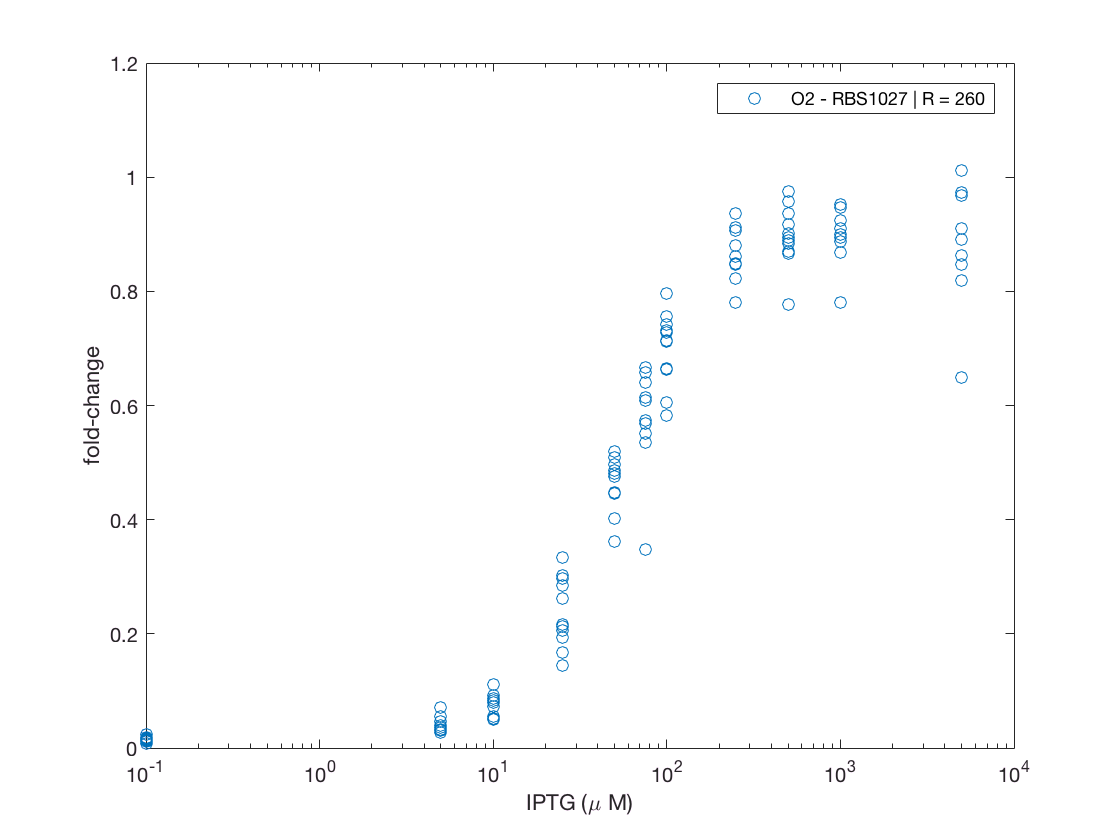

semilogx(df_fit.IPTG_uM, df_fit.fold_change_A, 'o')
xlabel('IPTG (\mu M)')
ylabel('fold-change')
legend('O2 - RBS1027 | R = 260')

## Plot mean and standard error

% Extract the unique IPTG concentrations
IPTG = unique(df_fit.IPTG_uM);

% Initialize arrays to save mean, std and number of samples for each IPTG concentration
mean_fc = [];
sd_fc = [];
num_fc = [];
% Loop through each IPTG concentrations. Extract the data, compute the mean, SD
% and count the number of data points
for c=1:length(IPTG)
    % First step: Extract the data
    df_tmp = table2array(df_fit(df_fit.IPTG_uM==IPTG(c), 'fold_change_A'));
    % Second step: compute mean fc and store it
    mean_fc(c) = mean(df_tmp);
    % Third step: compute standard deviation and store it
    sd_fc(c) = std(df_tmp);
    % Fourth and last step: count the number of data points and store them
    num_fc(c) = length(df_tmp);
end %for

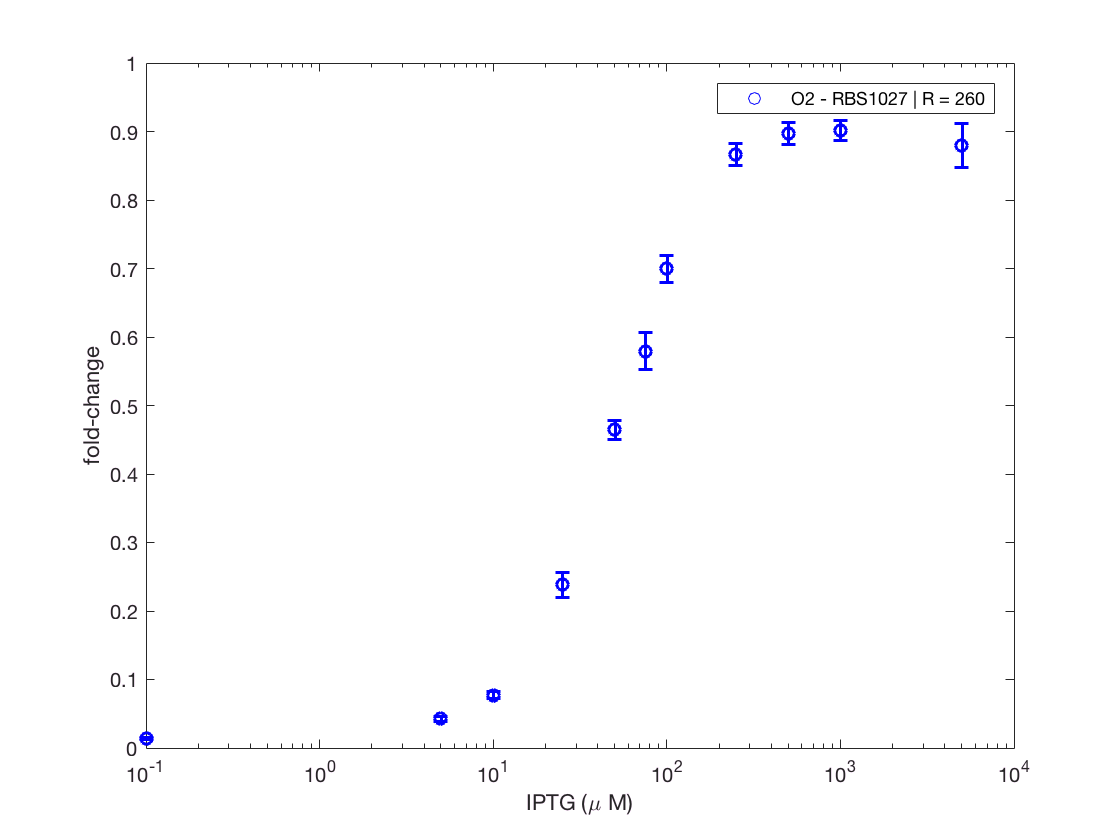

% Plot mean and error bars
clf
semilogx(IPTG, mean_fc, 'ob')
hold on
errorbar(IPTG, mean_fc, sd_fc ./ sqrt(num_fc), 'ob', 'Linewidth', 1.5)
xlabel('IPTG (\mu M)')
ylabel('fold-change')
legend('O2 - RBS1027 | R = 260')
hold off

## Defining functions for $p_{act}$ and fold-change

Let's test these functions by plotting the fold-change for some parameter values.

% Defining the parameters for the function
R = 130; % repressors / cell
epsilon_R = -13.9; % kBT
ea = 5; % kBT
ei = -1; % kBT
epsilon = 4.5; % kBT
%  Define range of IPTG in log-scale
IPTG_array = logspace(-1, 4, 100); % µM

%  Let's compute the fold-change using these parameters
fc_thry = fold_change(IPTG_array, ea, ei, R, epsilon_R, epsilon);

Let's now plot the fold-change

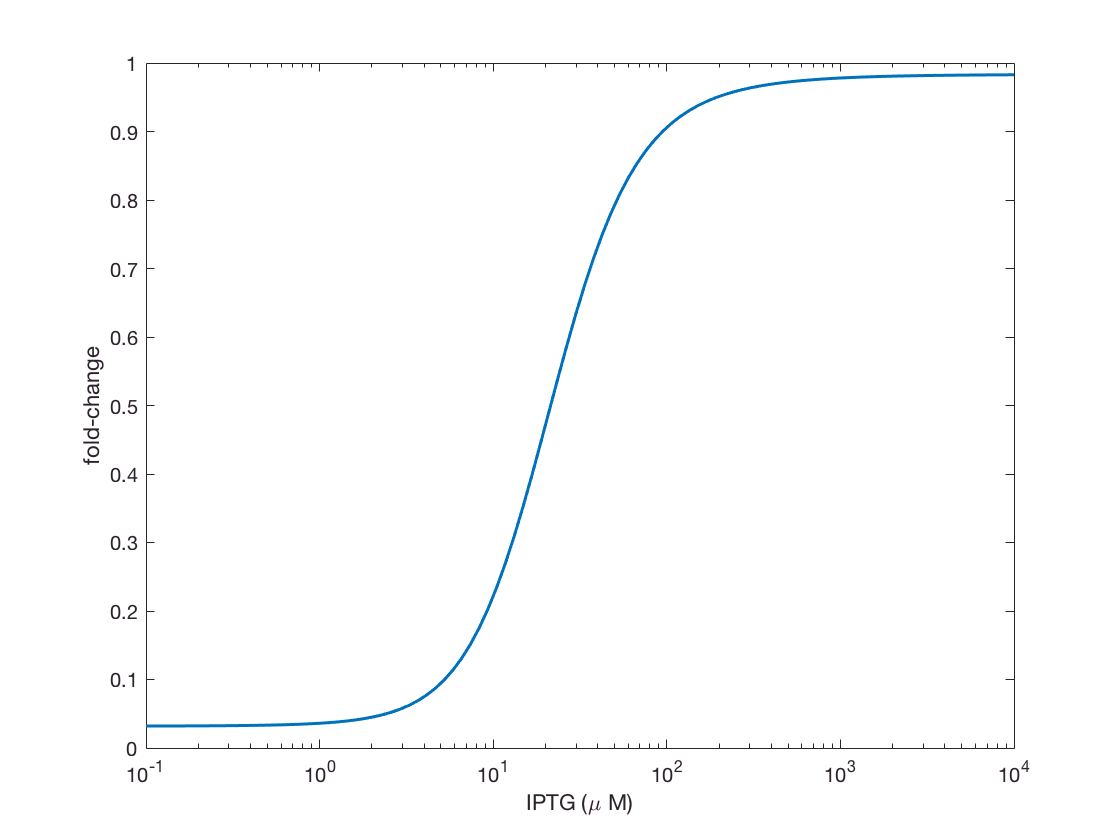

% Plot IPTG vs fold-change
semilogx(IPTG_array, fc_thry, 'Linewidth', 1.5)
xlabel('IPTG (\mu M)')
ylabel('fold-change')

## Define the log posterior $\log (\varepsilon \mid D)$

Let's test the function by ploting the log posterior for a grid of values

% Parameter values to plot
ea = linspace(4, 6, 100);
ei = linspace(-0.3, -0.9, 100);
epsilon = 4.5; %kBT
% make a grid to plot
[ea_grid, ei_grid] = meshgrid(ea, ei);

% compute the log posterior
indep_var = table2array(df_fit(:, {'IPTG_uM', 'repressors', 'binding_energy'}));
dep_var = df_fit.fold_change_A;

log_posterior = zeros(size(ea_grid));
for i=1:length(ea)
    for j=1:length(ei)
        log_posterior(i, j) = log_post([ea_grid(i, j), ei_grid(i, j)],...
                                       indep_var, dep_var, epsilon);
    end %for 2
end %for 1
log_posterior = log_posterior - max(log_posterior(:));

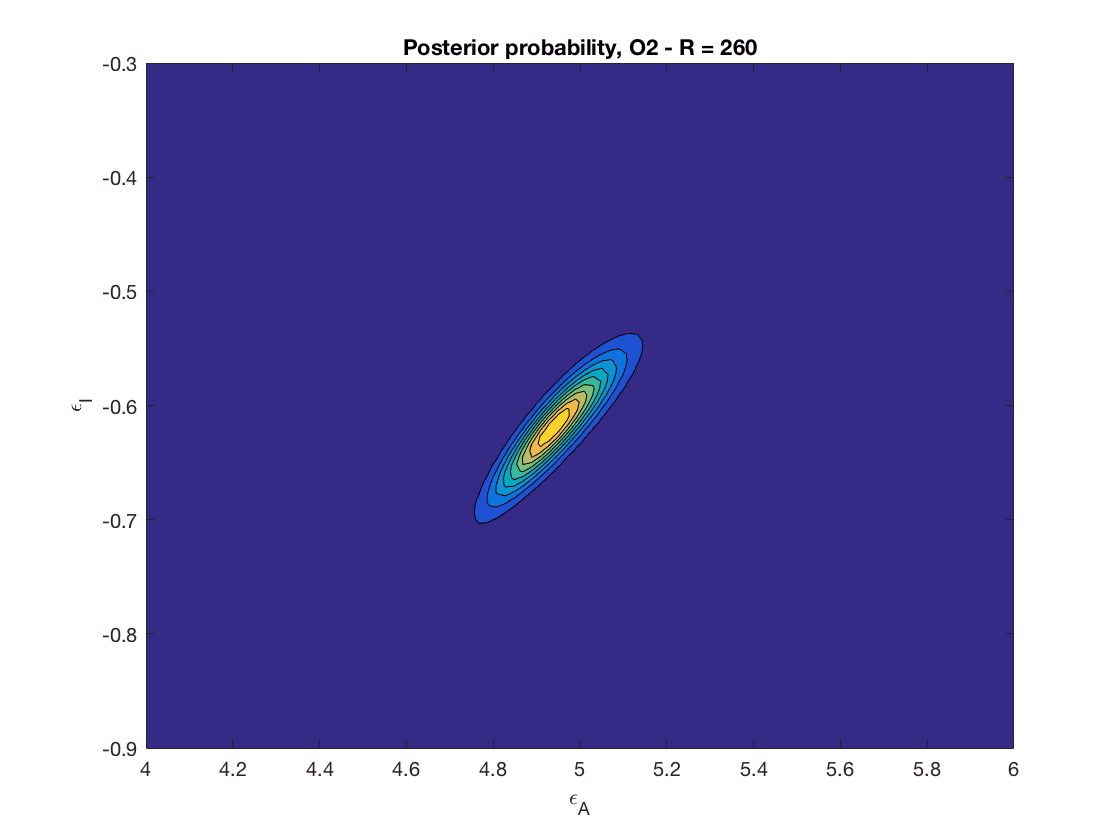

% plot the results
contourf(ea_grid, ei_grid, exp(log_posterior))
xlabel('\epsilon_A')
ylabel('\epsilon_I')
title('Posterior probability, O2 - R = 260')

## Find the most probable parameters by optimization

% compute the log posterior
indep_var = table2array(df_fit(:, {'IPTG_uM', 'repressors', 'binding_energy'}));
dep_var = df_fit.fold_change_A;
epsilon = 4.5;

p0 = [5, -0.55]; % inital parameter guess

% Define anonymous functions to compute the residuals with our data
residuals = @(param)resid(param, indep_var, dep_var, epsilon);
% Perform least-squares minimization
options.Algorithm = 'levenberg-marquardt';
popt = lsqnonlin(residuals, p0,[],[], options)


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the default value of the function tolerance.

<stopping criteria details>



popt =     4.9400   -0.6194


Ka = exp(popt(1))

Ka = 139.7638

Ki = exp(popt(2))

Ki = 0.5383

## Compute optimization with alternative function to obtain the Hessian Matrix at the most probable parameter values

resid_sqr = @(param)-log_post(param, indep_var, dep_var, epsilon);
[popt_fmincon,fval,exitflag,output,lambda,grad,hessian] = fmincon(resid_sqr, p0);


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the default value of the step size tolerance and constraints are 
satisfied to within the default value of the constraint tolerance.

<stopping criteria details>



popt_fmincon

popt_fmincon =     4.9400   -0.6194


hessian

hessian =    1.0e+03 *

    1.1609   -2.9768
   -2.9768    8.5894


## Plot the theoretical prediction given the experimental data

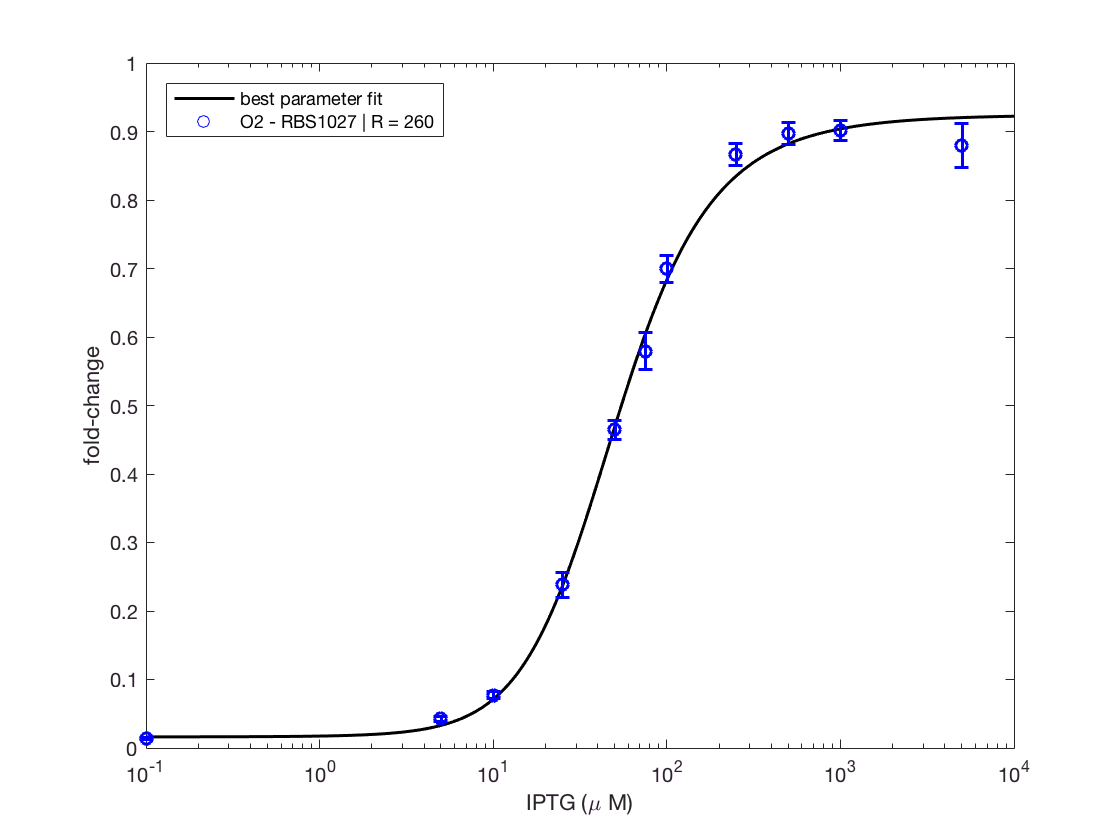

% Define the range of IPTG concentrations to evaluate the theoretical prediction
IPTG_array = logspace(-1, 4, 200);
% Evaluate the theoretical fold-change given the optimal parameters
fc_theory = fold_change(IPTG_array, popt_fmincon(1), popt_fmincon(2), 130, -13.9, 4.5);

% Extract the unique experimental IPTG concentrations
IPTG = unique(df_fit.IPTG_uM);

clf
semilogx(IPTG_array, fc_theory, 'k-', 'Linewidth', 1.5)
hold on
semilogx(IPTG, mean_fc, 'ob')
errorbar(IPTG, mean_fc, sd_fc ./ sqrt(num_fc), 'ob', 'Linewidth', 1.5)
xlabel('IPTG (\mu M)')
ylabel('fold-change')
legend('best parameter fit', 'O2 - RBS1027 | R = 260', 'Location', 'northwest')
hold off

## Computing an error-bar for the parameters

cov = inv(hessian)

cov =     0.0077    0.0027
    0.0027    0.0010
